# MatNWB Optical Physiology Tutorial for GraFT Use

## Introduction

In this tutorial, we will show how to create an optical physiology experiment with standard two-photon imaging data, using NeuroFinder data as simulated data.  The graft_demo_nwb.mlx tutorial will then demonstrate how to properly read the NWB file for GraFT use. 

Note: This tutorial has been modified slightly from the original [MatNWB Optical Physiology Tutorial](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/ophys.html) for proper [GraFT](https://github.com/adamshch/GraFT-analysis) use.  For more questions regarding NWB, it is recommended to first work through the [Introduction to MatNWB tutorial](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/intro.html), which demonstrates installing MatNWB and creating an NWB file with subject information, animal position, and trials, as well as writing and reading NWB files with varying file formats in MATLAB.

## Set up Paths & Misc Startups

mydir = pwd;                                                               % assuming running from tutorial folder
addpath(genpath(mydir(1:idx(end)-1)));                                     % Add all the files in the repo
ncores       = feature('numcores');                                        % Sets number of cores
core_percent = 1;                                                          % Sets the percent of cores to use
if isempty(gcp('nocreate'))
    parpool(ceil(core_percent*ncores),'IdleTimeout',5000);                 % If no parpool, make one
end

warning(sprintf('Using %d cores for parpool. Change var core_percent above if necessary',ceil(core_percent*ncores)));
RandStream.setGlobalStream(RandStream('mt19937ar'));                       % Set the random stream

## Download and load NeuroFinder data

fprintf('Loading Neurofinder data...\n')

Loading Neurofinder data...


data.nam = 'neurofinder.02.00';                                            % Create the name of the data to check for
if ~exist(data.nam,'file')                                                 % download file if it doesn't exist in the directory
    fprintf('Neurofinder data not detected, downloading data now...\n')
    url         = 'https://s3.amazonaws.com/neuro.datasets/challenges/neurofinder/neurofinder.02.00.zip';
    filename    = 'neurofinder.02.00.zip';
    outfilename = websave(filename,url);
    unzip(filename);
    clear url filename                                                     % Clear un-needed variables
end

data.dirname = fullfile(data.nam, 'images');                               % Get the directory name
data.files   = dir(fullfile(data.dirname,'*.tiff'));                       % Get all of  the filenames (look for tiff files)
data.fname   = fullfile(data.dirname, data.files(1).name);                 % Create a full-file name to point to the first file (used to get movie sizes)
data.Fsim    = imread(data.fname);                                         % Read in the first file
data.Fsim    = zeros(size(data.Fsim,1),size(data.Fsim,2),...
    length(data.files));   % Initialize the data array

for ll = 1:length(data.files)
    fname = fullfile(data.dirname, data.files(ll).name);
    data.Fsim(:,:,ll) = imread(fname);
end

data.Fsim = im2double(data.Fsim);
clear ll fname                                                             % Clear intermediary variables
fprintf('...done\n')

...done


## Set up the NWB file

An NWB file represents a single session of an experiment.  Each file must have a session_description, identifier, and session start time.  Create a new `NWBFile` object with those and additional metadata.  For all MatNWB functions, we use the Matlab method of entering keyword argument pairs, where arguments are entered as name followed by value.

nwb = NwbFile( ...
    'session_description', 'mouse in open exploration',...
    'identifier', 'Mouse5_Day3', ...
    'session_start_time', datetime(2018, 4, 25, 2, 30, 3), ...
    'general_experimenter', 'My Name', ... % optional
    'general_session_id', 'session_1234', ... % optional
    'general_institution', 'University of My Institution', ... % optional
    'general_related_publications', 'DOI:10.1016/j.neuron.2016.12.011'); % optional
nwb

nwb =   NwbFile with properties:

                                             nwb_version: '2.5.0'
                                        file_create_date: []
                         general_source_script_file_name: []
                                              identifier: 'Mouse5_Day3'
                                     session_description: 'mouse in open exploration'
                                      session_start_time: 2018-04-25T02:30:03.000000-07:00
                               timestamps_reference_time: []
                                             acquisition: [0×1 types.untyped.Set]
                                                analysis: [0×1 types.untyped.Set]
                                                 general: [0×1 types.untyped.Set]
                                 general_data_collection: []
                                         general_devices: [0×1 types.untyped.Set]
               

## Optical Physiology

Optical physiology results are written in four steps:

- Create imaging plane

- Acquired two-photon images

- Image segmentation

- Fluorescence and dF/F responses

Note: This tutorial is focused on [GraFT](https://github.com/adamshch/GraFT-analysis) functionality, please refer to [MatNWB Optical Physiology Tutorial](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/ophys.html) to learn about steps 3 & 4. 

### Imaging Plane

First, you must create an [`ImagingPlane`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ImagingPlane.html) object, which will hold information about the area and method used to collect the optical imaging data.  This requires creation of a [`Device`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Device.html) object for the microscope and an [`OpticalChannel`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/OpticalChannel.html) object.  Then you can create an [`ImagingPlane`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ImagingPlane.html).

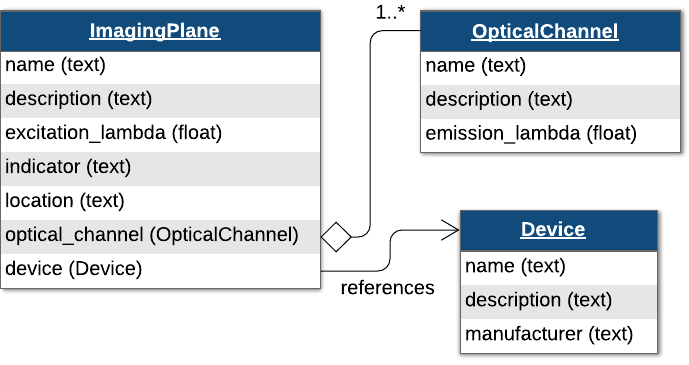

optical_channel = types.core.OpticalChannel( ...
    'description', 'description', ...
    'emission_lambda', 500.);

device = types.core.Device();
nwb.general_devices.set('Device', device);

imaging_plane_name = 'imaging_plane';
imaging_plane = types.core.ImagingPlane( ...
    'optical_channel', optical_channel, ...
    'description', 'a very interesting part of the brain', ...
    'device', types.untyped.SoftLink(device), ...
    'excitation_lambda', 600., ...
    'imaging_rate', 5., ...
    'indicator', 'GFP', ...
    'location', 'my favorite brain location');

nwb.general_optophysiology.set(imaging_plane_name, imaging_plane);

### Storing raw optical physiology data

Now that you have your [`ImagingPlane`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ImagingPlane.html), you can create a [`TwoPhotonSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/TwoPhotonSeries.html) the class representing two photon imaging data. [`TwoPhotonSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/TwoPhotonSeries.html), like [`SpatialSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/SpatialSeries.html), inherits from [`TimeSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/TimeSeries.html).

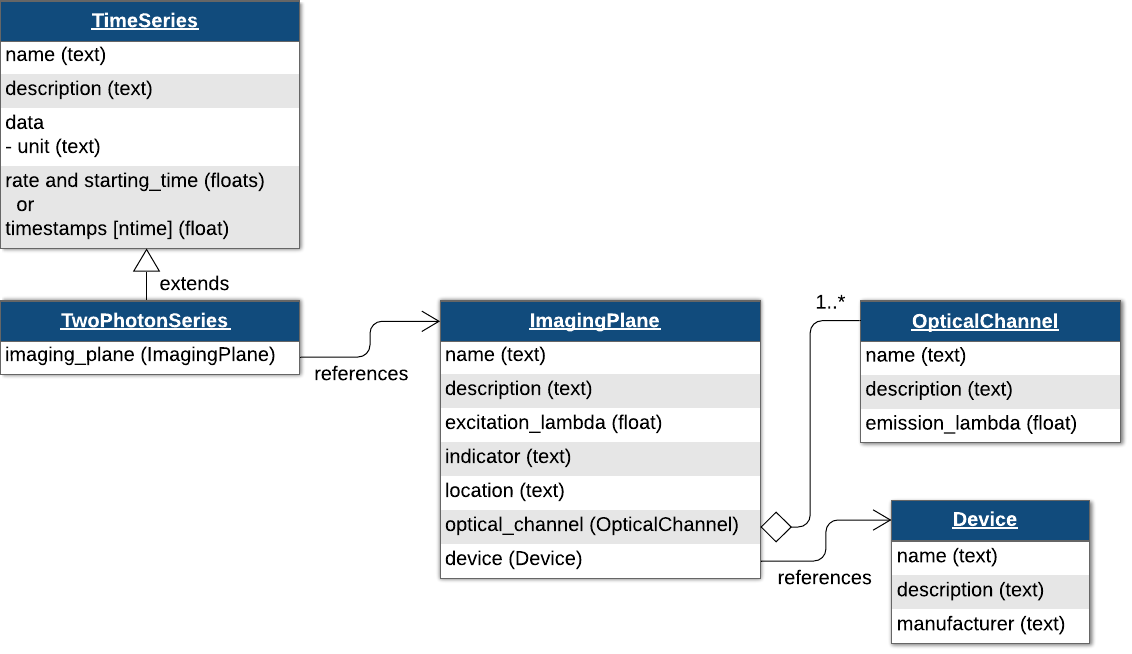

From here you have two options.  The first option is to supply the image data using the `data` argument.  The other option is the provide a path the images.  These two options have trade-offs, so it is worth spending time considering how you want to store this data.

#### Adding the data directly to the NWBFile

image_series = types.core.TwoPhotonSeries( ...
    'imaging_plane', types.untyped.SoftLink(imaging_plane), ...
    'starting_time', 0.0, ...
    'starting_time_rate', 3.0, ...
    'data', data.Fsim, ...
    'data_unit', 'lumens');

nwb.acquisition.set('TwoPhotonSeries', image_series);

Write the NWB file

nwbExport(nwb, 'ophys_graft_tutorial.nwb');

## Reading the NWB file

read_nwb = nwbRead('ophys_graft_tutorial.nwb', 'ignorecache');

Data arrays are read passively from the file.  Calling `TimeSeries.data` does not read the data values, but presents an HDF5 object that can be indexed to read data. 

read_nwb.acquisition.get('TwoPhotonSeries').data

ans =   DataStub with properties:

    filename: 'ophys_graft_tutorial.nwb'
        path: '/acquisition/TwoPhotonSeries/data'
        dims: [512 512 8000]
       ndims: 3
    dataType: 'double'


This allows you to conveniently work with datasets that are too large to fit in RAM all at once. Access the data in the matrix using the `load` method. 

`load` with no input arguments reads the entire dataset:

read_nwb.acquisition.get('TwoPhotonSeries').data.load;

If all you need is a section of the data, you can read only that section by indexing the `DataStub` object like a normal array in MATLAB. This will just read the selected region from disk into RAM.  This technique is particularly useful if you are dealing with a large dataset that is too big to fit entirely into your available RAM.

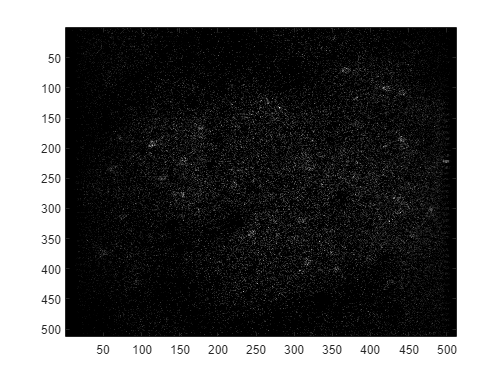

im_test = read_nwb.acquisition.get('TwoPhotonSeries').data(:,:,1);
imagesc(im_test)
colormap gray

# Learn more about NWB!

### See the [API documentation](https://neurodatawithoutborders.github.io/matnwb/doc/index.html) to learn what data types are available.

## Other MatNWB tutorials

- [Extracellular electrophysiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/ecephys.html)

- [Intracellular electrophysiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/icephys.html)

## Python tutorials

See our tutorials for more details about your data type:

- [Extracellular electrophysiology](https://pynwb.readthedocs.io/en/stable/tutorials/domain/ecephys.html#sphx-glr-tutorials-domain-ecephys-py)

- [Calcium imaging](https://pynwb.readthedocs.io/en/stable/tutorials/domain/ophys.html#sphx-glr-tutorials-domain-ophys-py)

- [Intracellular electrophysiology](https://pynwb.readthedocs.io/en/stable/tutorials/domain/icephys.html#sphx-glr-tutorials-domain-icephys-py)

**Check out other tutorials that teach advanced NWB topics:**

- [Iterative data write](https://pynwb.readthedocs.io/en/stable/tutorials/general/iterative_write.html#sphx-glr-tutorials-general-iterative-write-py)

- [Extensions](https://pynwb.readthedocs.io/en/stable/tutorials/general/extensions.html#sphx-glr-tutorials-general-extensions-py)

- [Advanced HDF5 I/O](https://pynwb.readthedocs.io/en/stable/tutorials/general/advanced_hdf5_io.html#sphx-glr-tutorials-general-advanced-hdf5-io-py)